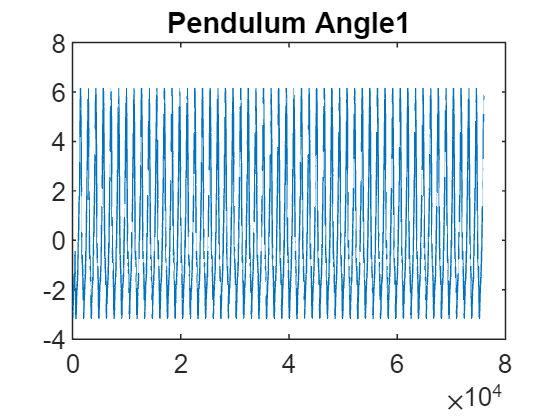

clear
close all
load("LinkedPendulum_NoInput_2.mat");

x1 = pendulum_angle(1:end); %2873
y1 = rotor_angle(1:end);

load("Edukit_Step_Response_Rotor_Angle_2pend_no_input_3_3_acquisizioni.mat");
x2 = pendulum_angle(1:end);
y2 = rotor_angle(1:end);


plot(x1);
title("Pendulum Angle1")

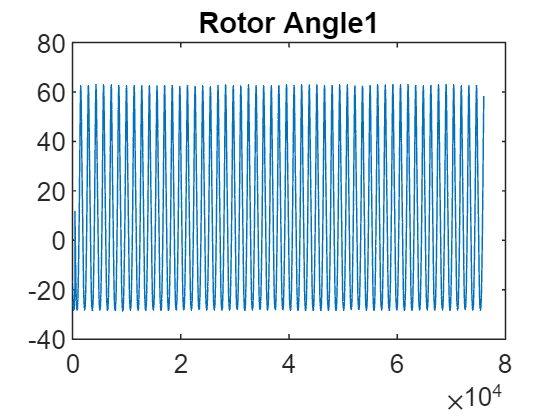

plot(y1);
title("Rotor Angle1")

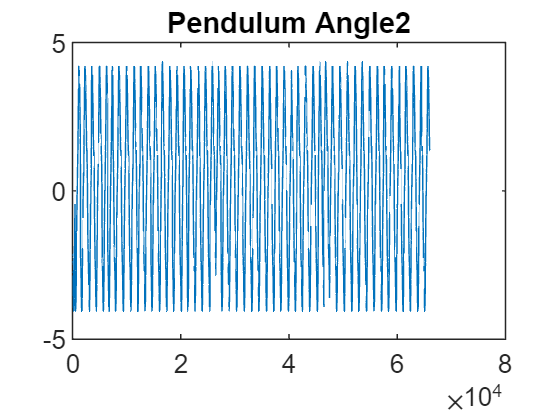


plot(x2);
title("Pendulum Angle2")

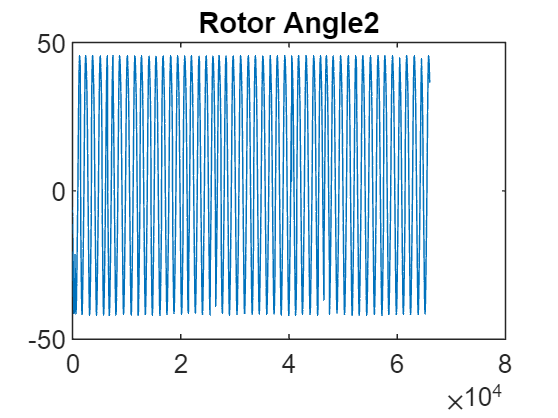

plot(y2);
title("Rotor Angle2")

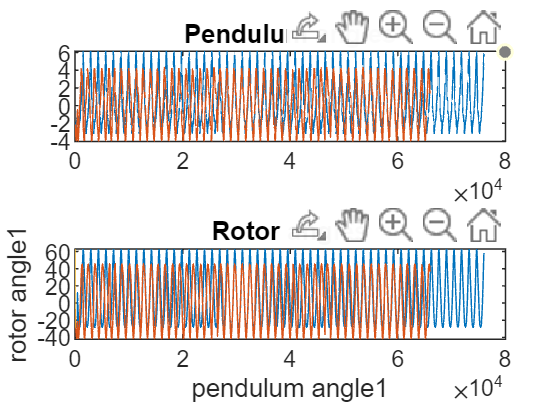


subplot(2,1,1)
plot(x1)
hold on
plot(x2)
title('Pendulum angles')
subplot(2,1,2)
plot(y1)
hold on
plot(y2)
title('Rotor angles')



plot(x1,y1)
xlabel("pendulum angle1")
ylabel("rotor angle1")

Il transitorio iniziale delle acquisizioni è stato rimosso. Inoltre, le acquisizioni sono state tagliate in modo che l'ultimo  ed il primo sample avessero un ampiezza molto simile.

Si osserva chiaramente un **Limit Cycle. ODDIO avvocato.. è una grandezza rispetto a se stessa, non è un phase portrait (dove si vede invece la traiettoria siccome si plotta x1,x2)**

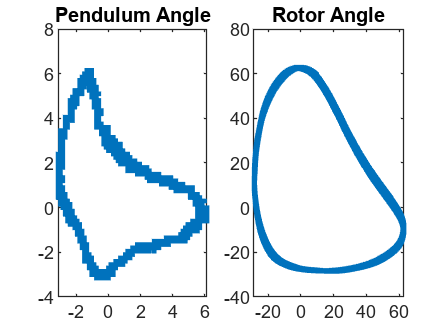


for i=1:1000
    subplot(1,2,1)
    plot(x1,[x1(i+1:end) x1(1:i)],'.');
    title("Pendulum Angle")
    subplot(1,2,2)
    plot(y1,[y1(i+1:end) y1(1:i)],'.');
    title("Rotor Angle")
    if mod(i,10)==0
    pause
    end

end